# 非線形モデル予測制御を利用した非断熱連続攪拌タンク反応器（CSTR）プラントの生成物の濃度制御

本例題では、CSTRプラントの反応物の濃度制御を非線形モデル予測制御（NMPC）によって行う方法を示す。

CSTRの構成は下図の通りである。

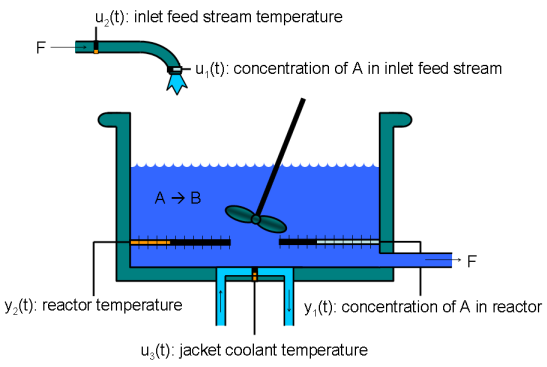

図1　CSTRのシステム構成（引用：MathWorks ヘルプドキュメントより）

CSTRプラントは反応物Aの濃度を一定の品質となるように制御を行うことが目標となるが、それには、供給試料の濃度u1、温度u2、ならびにタンクの被覆冷却温度u3の

3つの外生入力が反応物の濃度y1及び反応器内温度y2に影響を及ぼすMIMOシステムであり、非線形性の強いシステムである。

プラントのダイナミクスは、タンク内が十分に攪拌されていると仮定すると反応物Aの濃度と温度に関し、以下の非線形システムとして記述される。


$$\begin{array}{l}
\frac{dC_A \left(t\right)}{d\;t}=\frac{F\left(C_{\textrm{Ai}} -C_A \right)}{V}-k_0 C_A e\left(-\frac{E}{R\;T}\right)\\
\frac{d\;T\left(t\right)}{d\;t}=\frac{F\left(T_i -T\right)}{V}-\frac{C_A Hk_0 \left(-\frac{E}{R\;T}\right)}{c_p \rho }-\frac{\textrm{UA}\left(\left(T-T_j \right)\right)}{c_p \rho V}
\end{array}$$
 

主なパラメーター名：

$C_A$：反応物Aの濃度、$T$：反応容器内温度、$F$：供給試料の流量、$V$：タンク容積、$k_0$：非熱定数、$E$：活性化エネルギー

$R\;$：ガス定数、$c_p$：熱容量、$\rho$：密度、$\mathrm{U}$：温度転移係数、$\mathrm{A}$：熱交換面積（冷却液/容器面積）

CSTRでは、タンク壁に流れる冷却温度u3(${=T}_j$)を操作量として、反応物の濃度$C_A$を制御する。

このとき、センサで観測できるのは反応容器内の温度Tのみとし、濃度$C_A$は観測できない出力とする。

clc,clear
open_system('cstr_nmpc_ctrl')   %モデルの起動

プラントの初期状態などの各種パラメーター

Ts = 0.1;           %サンプリング時間
CA0 = 8.5698;       %濃度の初期値
T0 = 311.2639;      %温度の初期値
x0 = [CA0;T0];
CAi = 10;           %供給試料の濃度（一定値）
Ti = 298.15;        %供給試料の温度
Tc0 = 298.15;       %冷却温度の初期値
u0 = [CAi;Ti;Tc0];
nx = 2;             % Number of state
ny = 2;             % Number of output  
nu = 1;             % Number of input
nd = 1;             % Number of disturbance

NMPCの調整パラメーターを以下に設定する。

params.stateFunction = 'stateFcn';          % State function
params.measurementFunction = 'measurement'; % Measurement function
params.Q = diag([50,0]);                           %制御量の重み
params.R = 0.1;                           %操作量の重み
params.PredictiveHorizon = 10;          %予測ホライズンの長さ
params.ControlHorizon = 2;              %制御ホライズンの長さ
params.dMV_max = 2;                     %操作量の変化率制約
params.dMV_min = -2;
params.MV_scalefactor = 300;             %操作量のスケールゲイン
params.OV_scalefactor = [7;300];         %出力のスケールゲイン
params.initialconditionMV = u0(3);      %操作量の初期値
params.initialconditionState = x0;
params.IterationMax = 100;              %反復の最大回数

状態推定に使用する拡張カルマンフィルターのパラメーターを設定する。

Bv = eye(length(x0));                   %システムノイズの入力ベクトル
Q = diag([1 1]);                        %システムノイズの重み
R = 1;                                  %観測ノイズの重み
xhat0 = x0;                             %推定値の初期値
P0 = eye(length(x0));                   %共分散行列の初期値

シミュレーション実行

% Sim
Tsim = 200;
tic
sim('cstr_nmpc_ctrl',Tsim)
toc

経過時間は 7.556332 秒です。
